clearvars
close all
clc

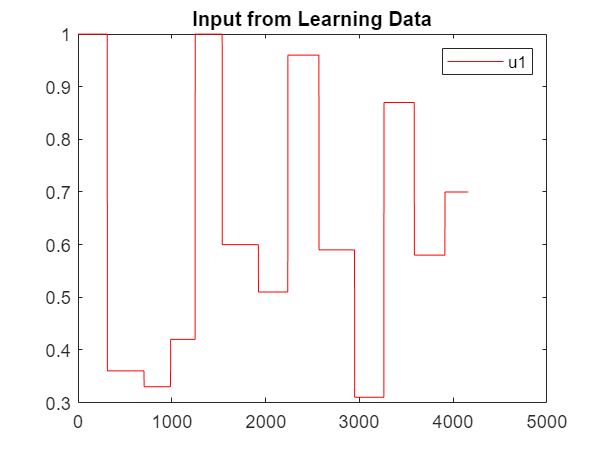

% data1 = readmatrix('mentah_asli_1_data_learning_20230331(data1).xlsx');
data1 = readmatrix('mentah_asli1_datatraining_31.xlsx');
u_lama1 = data1(:,1);
ys_lama1 = data1(:,2);

% data2 = readmatrix('mentah_asli_2_data_test_20230329(data2).xlsx');
data2 = readmatrix('mentah_asli2_datatesting_14.xlsx');
u_lama2 = data2(:,1);
ys_lama2 = data2(:,2);

% data3 = readmatrix('mentah_asli_3_data_test_20230328(data3).xlsx');
data3 = readmatrix('mentah_asli3_datatesting_16.xlsx');
u_lama3 = data3(:,1);
ys_lama3 = data3(:,2);

% data4 = readmatrix('mentah_asli_4_data_test_20230314(data4).xlsx');
data4 = readmatrix('mentah_asli4_datavalidation_17.xlsx');
u_lama4 = data4(:,1);
ys_lama4 = data4(:,2);


div = 1;
for i=1:(length(u_lama1)/div)
    u1(i,:) = u_lama1(div*(i-1)+div,:);
    ys1(i,:) = ys_lama1(div*(i-1)+div,:);
end

div = div;
for i=1:(length(u_lama2)/div)
    u2(i,:) = u_lama2(div*(i-1)+div,:);
    ys2(i,:) = ys_lama2(div*(i-1)+div,:);
end

div = div;
for i=1:(length(u_lama3)/div)
    u3(i,:) = u_lama3(div*(i-1)+div,:);
    ys3(i,:) = ys_lama3(div*(i-1)+div,:);
end

div = div;
for i=1:(length(u_lama4)/div)
    u4(i,:) = u_lama4(div*(i-1)+div,:);
    ys4(i,:) = ys_lama4(div*(i-1)+div,:);
end


%rumus regresi
ys1 = (0.0002.*ys1.*ys1)-(0.0236*ys1)-31.331;
ys2 = (0.0002.*ys2.*ys2)-(0.0236*ys2)-31.331;
ys3 = (0.0002.*ys3.*ys3)-(0.0236*ys3)-31.331;
ys4 = (0.0002.*ys4.*ys4)-(0.0236*ys4)-31.331;


a=0;
b=1;
a1=0;
b1=100;
a2=0;
b2=100;
u1 = (b-a).*(u1./(b1-a1)) + a;
ys1 = (b-a).*(ys1./(b2-a2)) + a;

u2 = (b-a).*(u2./(b1-a1)) + a;
ys2 = (b-a).*(ys2./(b2-a2)) + a;

u3 = (b-a).*(u3./(b1-a1)) + a;
ys3 = (b-a).*(ys3./(b2-a2)) + a;

u4 = (b-a).*(u4./(b1-a1)) + a;
ys4 = (b-a).*(ys4./(b2-a2)) + a;


Ts = 1;
tt = (0:Ts:length(u1)-1).';
figure,
plot(tt,u1,'r');
legend('u1','location','northeast');
title('Input from Learning Data');

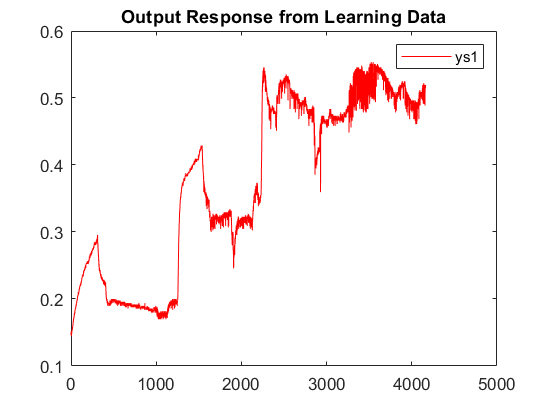


clear tt;
tt = (0:Ts:length(ys1)-1).';
figure,
plot(tt,ys1,'r'); 
legend('ys1','location','northeast');
title('Output Response from Learning Data');

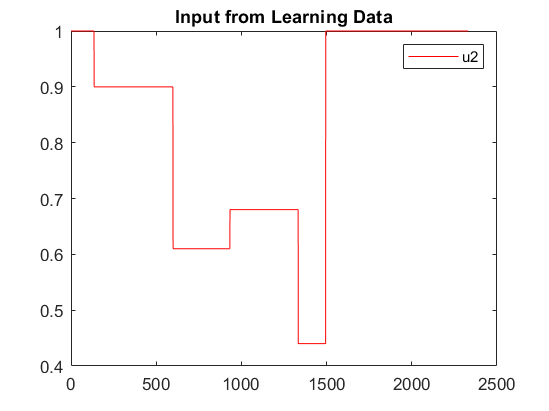


clear tt;
tt = (0:Ts:length(u2)-1).';
figure,
plot(tt,u2,'r');
legend('u2','location','northeast');
title('Input from Learning Data');

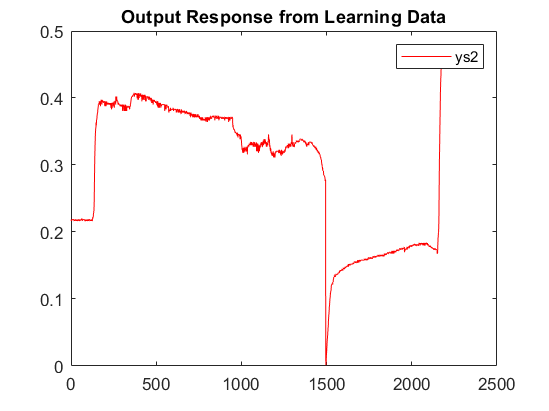


clear tt;
tt = (0:Ts:length(ys2)-1).';
figure,
plot(tt,ys2,'r'); 
legend('ys2','location','northeast');
title('Output Response from Learning Data');

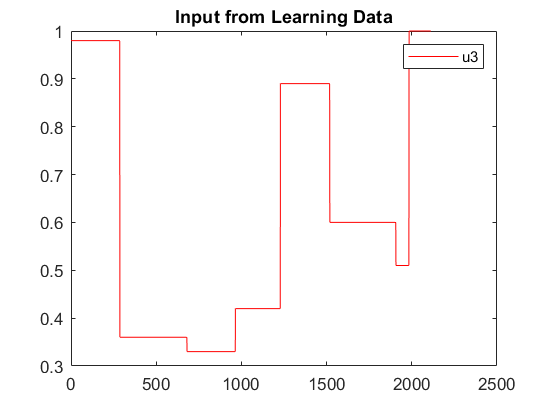


clear tt;
tt = (0:Ts:length(u3)-1).';
figure,
plot(tt,u3,'r');
legend('u3','location','northeast');
title('Input from Learning Data');

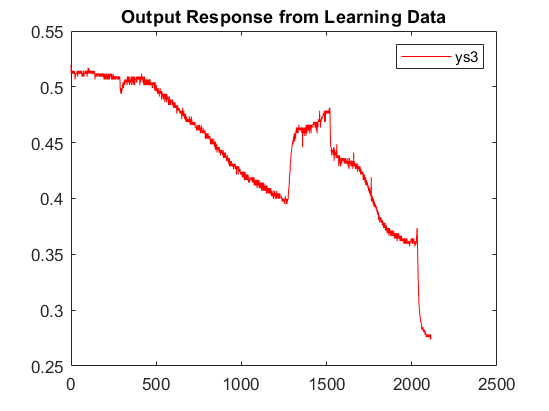


clear tt;
tt = (0:Ts:length(ys3)-1).';
figure,
plot(tt,ys3,'r'); 
legend('ys3','location','northeast');
title('Output Response from Learning Data');

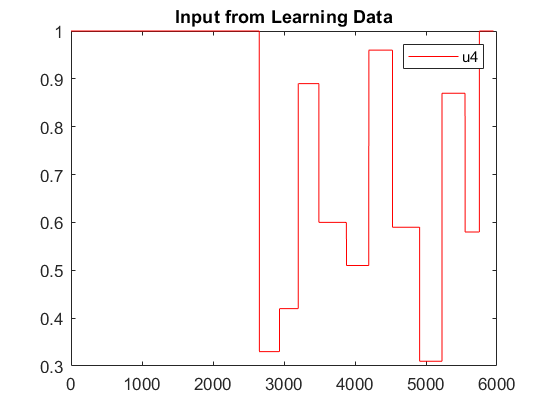


clear tt;
tt = (0:Ts:length(u4)-1).';
figure,
plot(tt,u4,'r');
legend('u4','location','northeast');
title('Input from Learning Data');

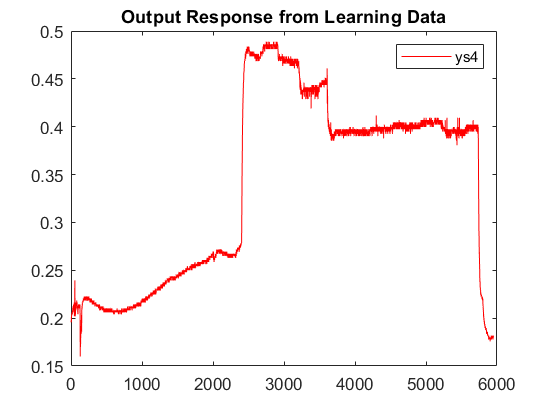


clear tt;
tt = (0:Ts:length(ys4)-1).';
figure,
plot(tt,ys4,'r'); 
legend('ys4','location','northeast');
title('Output Response from Learning Data');